# Arch Model Estimation

## **Exercise** 64

Exercise 64 asks us to download the data for the SP500 and the EUR/USD. Let's use our old friend `fetch` to do so:

clear all
clc
% Downloading the SP500 data: 
fred_sp500 = fetch(fred(), 'SP500')

fred_sp500 = struct with fields:
                 Title: ' S&P 500'
              SeriesID: ' SP500'
                Source: ' S&P Dow Jones Indices LLC'
               Release: ' Standard & Poors (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily, Close'
                 Units: ' Index'
             DateRange: ' 2010-02-05 to 2020-02-04'
           LastUpdated: ' 2020-02-04 7:10 PM CST'
                 Notes: ' The observations for the S&P 500 represent the daily index value at market close.  The Federal Reserve Bank of St. Louis and S&P Dow Jones Indices LLC have reached a new agreement on the use of Standard & Poors and Dow Jones Averages series in FRED. FRED and its associated services will include 10 years of daily history for Standard & Poors and Dow Jones Averages series.  The S&P 500 is regarded as a gauge of the large cap U.S. equities market. The index includes 500 leading companies in leading industries of the U.S. econ

% Downloading the EUR/USD data:
fred_euro = fetch(fred(), 'DEXUSEU')

fred_euro = struct with fields:
                 Title: ' U.S. / Euro Foreign Exchange Rate'
              SeriesID: ' DEXUSEU'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.10 Foreign Exchange Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' U.S. Dollars to One Euro'
             DateRange: ' 1999-01-04 to 2020-01-31'
           LastUpdated: ' 2020-02-03 3:49 PM CST'
                 Notes: ' Noon buying rates in New York City for cable transfers payable in foreign currencies.'
                  Data: [5500×2 double]


Let's begin by checking what is the range of these two imported series:

fred_sp500.DateRange

ans = ' 2010-02-05 to 2020-02-04'

fred_euro.DateRange

ans = ' 1999-01-04 to 2020-01-31'

We can see that the data in fred_sp500 has exactly the 10 years of data that we want. Therefore, let's use the date indices from `fred_sp500` to select the data from **fred_euro** for the same interval. But before doing this, we need to remove the NaN values from both series. Removing NaN values is important because otherwise our function to estimate the GARCH models won't work.

% Let's first get rid of the NaN values
fred_sp500.Data = fred_sp500.Data(~isnan(fred_sp500.Data(:,2)),:);
fred_euro.Data = fred_euro.Data(~isnan(fred_euro.Data(:,2)),:);
% Getting the vector with the relevant dates:
dates_sp = fred_sp500.Data(:,1);
dates_euro = fred_euro.Data(fred_euro.Data(:,1)>=dates_sp(1),1);
% Finally, getting sp500 and euro data for the last 10yrs:
sp500 = fred_sp500.Data(:,2);
euro = fred_euro.Data(fred_euro.Data(:,1)>=dates_sp(1), 2);

To conclude, let's just plot these two series:

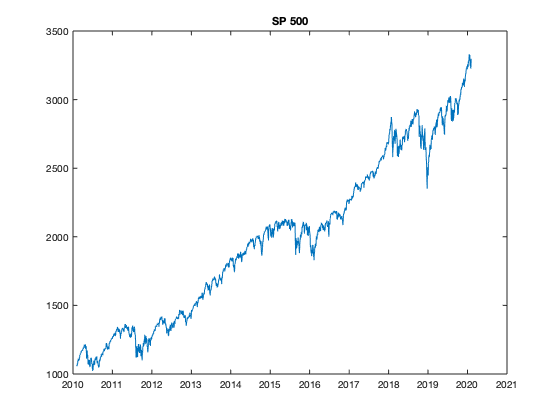

plot(dates_sp, sp500)
title('SP 500')
datetick('x')

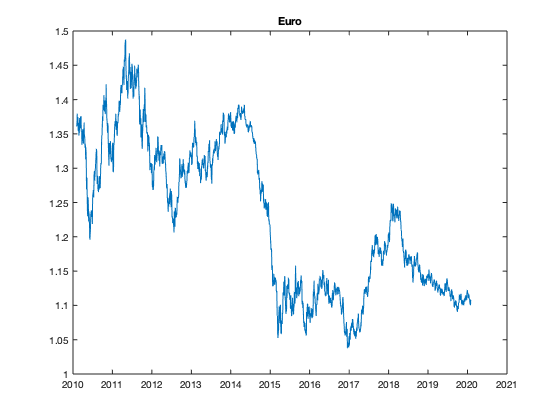

plot(dates_euro, euro)
title('Euro')
datetick('x')

## **Exercise** 65

Question 65 asks us to estimate both a GARCH(1,1) and a GJR-GARCH(1,1,1) for the returns of these two series. Therefore, let's first calculate the series of daily returns:

% Calculating returns:
r_sp = diff(log(sp500))*100;
r_euro = diff(log(euro))*100;
% Adjusting the date vectors:
dates_sp = dates_sp(2:end);
dates_euro = dates_euro(2:end);

Now let's take a look at the plots of returns:

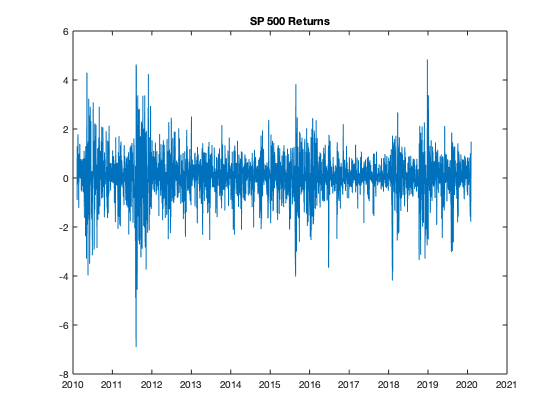

plot(dates_sp, r_sp)
title('SP 500 Returns')
datetick('x')

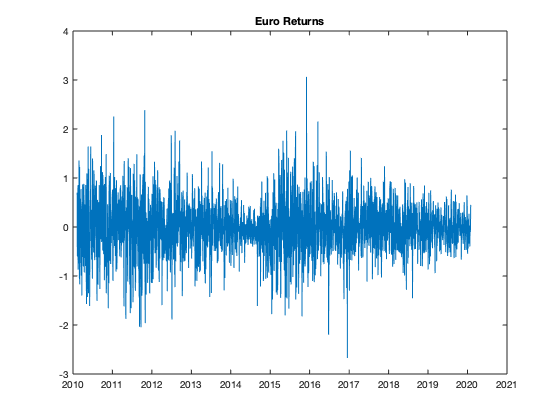

plot(dates_euro, r_euro)
title('Euro Returns')
datetick('x')

As you may already suspect, we are going to use a function from the MFE toolbox to estimate GARCH models. ARCH, GARCH, GJR-GARCH and TARCH models can be estimated using the `tarch` function. Let's check how this function works.

help tarch

  tarch(P,O,Q) parameter estimation with different error distributions:
  Normal, Students-T, Generalized Error Distribution, Skewed T
  Estimation of ARCH or GARCH models if o=0 and tarch_type=2
  Estimation of tarch or GJR asymmetric models if o>0 and tarch_type=1 or 2
 
  USAGE:
    [PARAMETERS] = tarch(EPSILON,P,O,Q)
    [PARAMETERS,LL,HT,VCVROBUST,VCV,SCORES,DIAGNOSTICS] = 
                                    tarch(EPSILON,P,O,Q,ERROR_TYPE,TARCH_TYPE,STARTINGVALS,OPTIONS)
 
  INPUTS:
    EPSILON      - A column of mean zero data
    P            - Positive, scalar integer representing the number of symmetric innovations
    O            - Non-negative scalar integer representing the number of asymmetric innovations (0
                     for symmetric processes)    
    Q            - Non-negative, scalar integer representing the number of lags of conditional
                     variance (0 for ARCH) 
    ERROR_TYPE   - [OPTIONAL] The error dist

Now we can use this `tarch` function to estimate the GARCH(1,1) and the GJR-GARCH(1,1,1) models. Let's begin by doing this for the returns of the SP500.

% Estimating a GARCH(1,1) for SP500 returns: 
[g11_p, g11_ll] = tarch(r_sp, 1, 0, 1)

____________________________________________________________
   Diagnostic Information

Number of variables: 3

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          3016.19                          35.3
     1          12          3012.73     0.00304285           9.58  
     2          16          3012.34              1           8.14  
     3          20           3011.2              1           3.82  
     4          24          3011.16              1            2.9  
     5          28          3011.03              1           3.33  
     6        

g11_p =      0.036433
      0.15599
       0.8026


g11_ll =       -3010.9


% Estimating a GJR-GARCH(1,1,1)for SP500 returns:
[gjr_p, gjr_ll] = tarch(r_sp, 1, 1, 1)


____________________________________________________________
   Diagnostic Information

Number of variables: 4

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           5          2947.55                          27.7
     1          15          2945.21     0.00408919             20  
     2          20          2943.83              1             13  
     3          25          2940.08              1           8.66  
     4          30          2939.13              1           7.06  
     5          35          2938.45              1           8.41  
     6       

gjr_p =      0.037953
   6.7745e-09
      0.29174
      0.81681


gjr_ll =       -2931.7


% Estimating a GARCH(1,1) for Euro/USD returns: 
[g11_p, g11_ll] = tarch(r_euro, 1, 0, 1)


____________________________________________________________
   Diagnostic Information

Number of variables: 3

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          1877.71                          12.3
     1          12          1873.56      0.0384321           8.86  
     2          16          1871.38              1           12.8  
     3          20          1867.14              1              2  
     4          24          1866.87              1           1.16  
     5          28          1866.75              1           0.68  
     6       

g11_p =     0.0005807
     0.026709
      0.97101


g11_ll =       -1866.7


% Estimating a GJR-GARCH(1,1,1) for Euro/USD returns: 
[gjr_p, gjr_ll] = tarch(r_euro, 1, 1, 1)


____________________________________________________________
   Diagnostic Information

Number of variables: 4

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           5          1878.77                          10.8
     1          15           1874.2      0.0369455           21.3  
     2          20          1870.09              1           7.15  
     3          25          1867.48              1           8.42  
     4          30          1862.76              1           4.06  
     5          35          1861.32              1           1.93  
     6       

gjr_p =    5.8846e-05
    0.0065481
     0.021564
      0.98168


gjr_ll =         -1860


## **Exercise** 66.a

We are now asked to comment on the asymmetry of these return distributions. In order to do so, the first step is to compare the robust with the non-robust parameter covariance matrices. So now let's estimate the GARCH(1,1) and GJR-GARCH(1,1,1) and save the values we need. 

Because the likelihood of the GJR-GARCH(1,1,1) model is larger in both cases, we will start with this model. If the asymmetric components proves to be significant (it looks like it will), we don't even need to do the analysis for the GARCH(1,1).

One can notice that, as it was the case with the `armaxfilter` function, MATLAB is showing us every iteration of the optimization algorithm. Since we are not really interested in seeing this, we can, as before, set the option for the `tarch` function not to display these iterations.

options.Display = 'none';

Ok. Now is time to turn to the estimation:

% Estimating a GJR-GARCH(1,1,1) for SP500 returns: 
[sp_p, sp_ll, sp_ht, sp_vcvr, sp_vcv] = tarch(r_sp, 1, 1, 1, [], [], [], options);

To see the difference between the robust and the non-robust parameter covariance matrices, let's compare the t-statistics based on them.

% T-stats based on the robust covariance:
sp_p./sqrt(diag(sp_vcvr))

ans =        6.3036
       1.7255
        7.433
        44.04


% T-stats based on the non-robust covariance:
sp_p./sqrt(diag(sp_vcv))

ans =        8.6239
      0.10659
       9.5441
       57.537


As we can see, the t-stats differ between the robust and non-robust estimators, possibly because of the non-normality of S&P 500 returns. Nevertheless, in both cases the same components are significant. One can notice that the "AR" component of the GJR-GARCH is highly significant while all the significance of the "MA" component is coming from the asymmetric response to shocks.

Now turning the analysis to the EUR/USD series:

% Estimating a GJR-GARCH(1,1,1) for SP500 returns: 
[euro_p, euro_ll, euro_ht, euro_vcvr, euro_vcv] = tarch(r_euro, 1, 1, 1, [], [], [], options);

To see the difference between the robust and the non-robust parameter covariance matrices, let's compare the t-statistics based on them.

% T-stats based on the robust covariance:
euro_p./sqrt(diag(euro_vcvr))

ans =        0.7665
        0.903
       3.4714
        172.1


% T-stats based on the non-robust covariance:
euro_p./sqrt(diag(euro_vcv))

ans =             0 -    0.54703i
       1.8707 +          0i
        4.577 +          0i
       397.21 +          0i


These results are very similar to those of the S&P 500. Nevertheless, we can see that the "AR" component is vastly more significant. This shows that volatility shocks in exchange rates are a lot more persistent than in equities (see PPP Puzzle). Another important difference is in the constant term. The GJR-GARCH(1,1,1) estimation shows that this term is not significant for the EUR/USD series. This is expected given the low unconditional volatility of exchange rates in developed markets.

## **Exercise** 66.b

After estimating and discussing GJR-GARCH(1,1,1) models, we are now asked to plot the variance and volatility fitted by these models. Let's start by plotting the fitted variances:

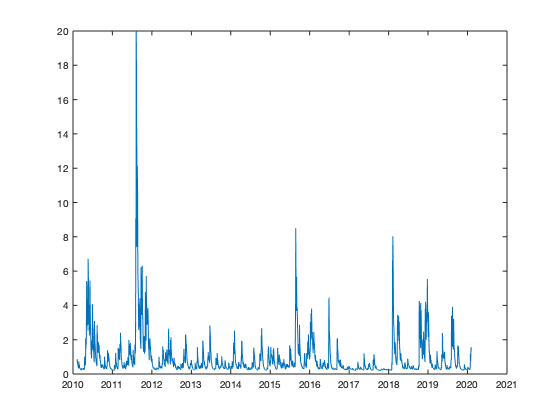

% Plotting the fitted variance for SP500:
plot(dates_sp, sp_ht)
datetick('x')

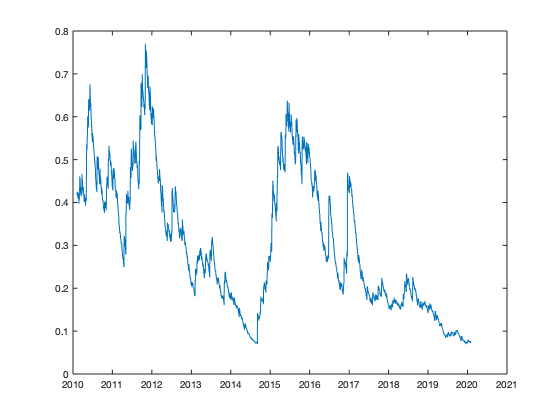

% Plotting the fitted variance for euro:
plot(dates_euro, euro_ht)
datetick('x')

We can see the existence of volatility clustering. Moreover, given the very high persistence of volatility in the EUR/USD series, the variance of this series presents a "random-walky" behaviour. These plot by themselves, however, are not very interesting to look at. Let's take a look at the plot of the fitted standard deviations next to the returns and absolute returns of the series.

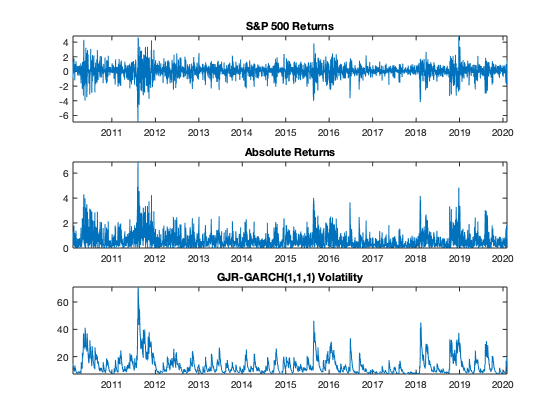

% Plotting fitted volatility and returns for SP500:
figure();
Y = {r_sp, abs(r_sp), sqrt(252*sp_ht)};
titles = {'S&P 500 Returns', 'Absolute Returns', 'GJR-GARCH(1,1,1) Volatility'};
for i=1:3
    subplot(3,1,i)
    plot(dates_sp,Y{i})
    axis tight
    title(titles{i})
    datetick('x','keeplimits')
end

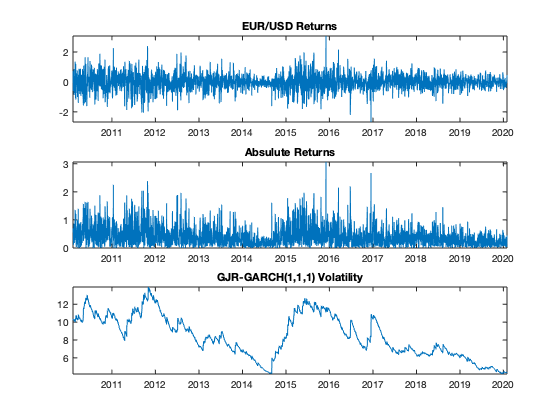

% Plotting fitted volatility and returns for Euro:
figure();
Y = {r_euro, abs(r_euro),  sqrt(252*euro_ht)};
titles = {'EUR/USD Returns', 'Absulute Returns','GJR-GARCH(1,1,1) Volatility'};
for i=1:3
    subplot(3,1,i)
    plot(dates_euro,Y{i})
    axis tight
    title(titles{i})
    datetick('x','keeplimits')
end

Plotting the volatility next to the returns of the series is very useful because it allows us to check the practical implications of our estimated volatility. Moreover, since volatility is in the same scale as returns, the numbers of our volatility charts are directly interpretable. In the case of the S&P500, we can see the effect of the different periods of volatility clustering on the returns. More interesting, however, are the results from the EUR/USD graphs. Given the very high persistence of the volatility of exchange rates, we can clearly see the longer periods of high and low volatility. 

## **Exercise** 66.c

We are finally asked to plot standardized returns (they are our residuals since we assuming they are mean zero). The first step is to construct the series of standardized residuals given their time varying volatility. To do so, we divide the vector of returns by our vector of fitted volatilities.

% Constructing SP500 standardized returns:
std_sp = r_sp./sqrt(sp_ht);
% Constructing Euro standardized returns:
std_euro = r_euro./sqrt(euro_ht);

The idea of this question is to observe the distribution  of the standardized returns and to compare it with the normal distribution. The MFE Toolbox has a function that estimates non-parametric density of a vector of data. This is the `pltdens` function. We will use this function to get the density of our standardized returns and compare them with a normal. Luckily, the MFE toolbox is also equipped with the function `normpdf` that generates the density of a normal distribution. 

help pltdens

  PURPOSE: Draw a nonparametric density estimate. 
 ---------------------------------------------------
  USAGE: [h f y] = pltdens(x,h,p,kernel)
         or pltdens(x) which uses gaussian kernel default
  where:
         x is a vector
         h is the kernel bandwidth 
           default=1.06 * std(x) * n^(-1/5); Silverman page 45
         p is 1 if the density is 0 for negative values
         k is the kernel type:
           =1 Gaussian (default)
         =2 Epanechnikov 
         =3 Biweight
         =4 Triangular
    A jittered plot of the 
    observations is shown below the density.
 ---------------------------------------------------
  RETURNS:
         h = the interval used
         f = the density
         y = the domain of support
         plot(y,f) will produce a plot of the density
  --------------------------------------------------
  SEE ALSO hist, histo
 ---------------------------------------------------



help normpdf

  Probability Density Function (PDF) of the Normal Distribution (Gaussian)
 
  USAGE:
    Y = normpdf(X,MU,SIGMA)
 
  INPUTS:
    X     - Normally distributed random variables
    MU    - Mean parameter
    SIGMA - Standard deviation parameter
 
  OUTPUTS:
    Y     - Probability density evaluated at x
 
  COMMENTS:
    SIGMA>0
 
    This is a clean room implementation that mimics the core function of
    MATLAB's normpdf.  
 
 
 
  See also normpdf, norminv, normrnd, normloglik

    Other functions named normpdf



Ok. Now that we know which functions we have to use, we can plot the densities of our standardized returns against the normal distribution. 

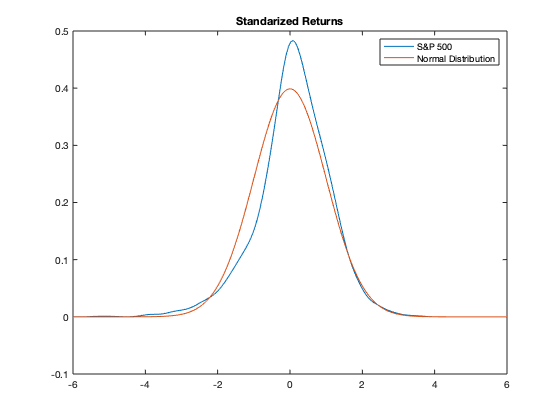

% Getting our SP500 density:
[~,y_sp,x_sp] = pltdens(std_sp);
% Getting the density for the normal:
normal_sp = normpdf(x_sp);
% Plotting SP500 vs normal
figure()    
plot(x_sp, [y_sp, normal_sp])
xlim([-6 6])
legend('S&P 500', 'Normal Distribution')
title('Standarized Returns')

We can see that our standardized S&P 500 returns are not exactly mean zero as the curve is a bit shifted to the right. In the centre of the distribution, there are more positive and less negative values than the normal. Another important property that shows in this figure is the "fat-tailness" of negative stock returns. We can see that towards the negative extreme values, our standardized returns have an occurrence which is higher than that of a normal distribution.

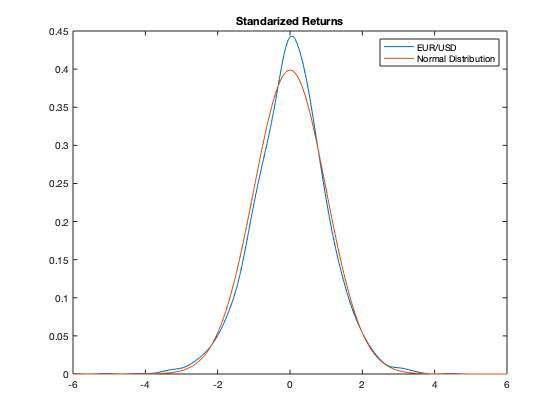

% Getting our Euro density:
[~,y_euro,x_euro] = pltdens(std_euro);
% Getting the density for the normal:
normal_euro = normpdf(x_euro);
% Plotting Euro vs normal
figure()    
plot(x_euro, [y_euro, normal_euro])
xlim([-6 6])
legend('EUR/USD', 'Normal Distribution')
title('Standarized Returns')

Finally, by looking at the last figure we can see that the standardized returns of the EUR/USD exchange rate are closer to a normal than the S&P500. At least, it seems like this series is pretty much mean zero. The curve is slightly shifted to the right and we have a higher concertation in the centre. The tails are also a fatter than the normal in both sides, showing the leptokurtosis of the density of the EUR/USD exchange rate.

To conclude, let's save the S&P 500 data since we will need to use it in the next exercises:

save sp_data r_sp dates_sp